# The Optical Depth limit to Receiving Droplet Size Information

By Andrew John Buggee

## Estimating the Fractional Absorption due to Multiple Scattering in a semi-infinte Cloud

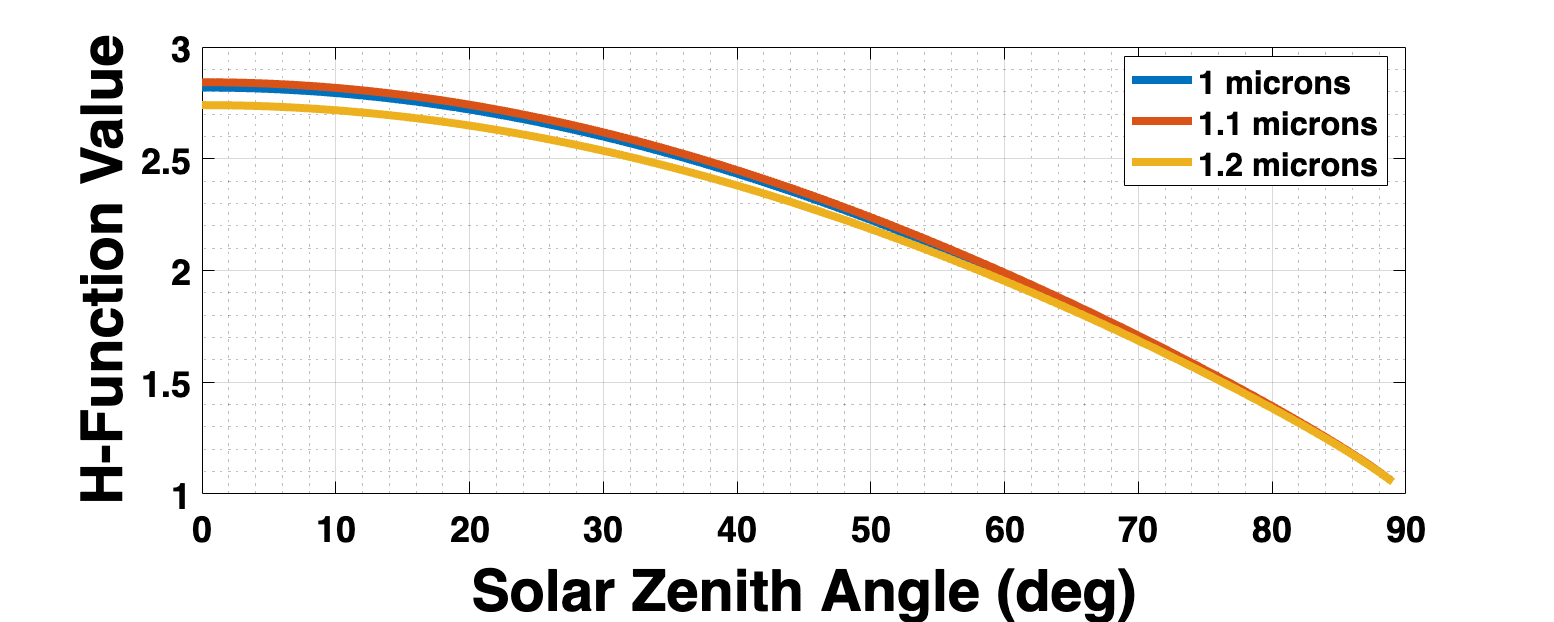

% Lets start by estimating the H function
% define a solar zenith angle
theta0 = 0:89;
mu0 = cosd(theta0);         % cosine of the solar zenith angle

% Pick a wavelength
wl_nm = [1000, 1100, 1200];                    % nanometers
wl_microns = wl_nm*(1e-3);      % microns
% Pick a droplet radius
r = [10,10,10];                     % microns

% compute the single scattering albedo

mie_prop = interp_mie_computed_tables([wl_nm',r'],'mono',false);
single_scattering_albedo = mie_prop(:,6);

% Or we can override the singlescattering value to be a specific number of
% interest
%single_scattering_albedo = [0.9996, 0.9998, 0.999]';

% Compute the H function value
H_func = H(mu0, single_scattering_albedo, 0);


% Lets plot the Results!

f = figure;
plot(theta0, H_func)
grid on; grid minor
xlabel('Solar Zenith Angle (deg)')
ylabel('H-Function Value')
legend(strcat(string(wl_microns),' microns'), 'Location',"best")
set(f, 'Position', [0 0 1000 400])

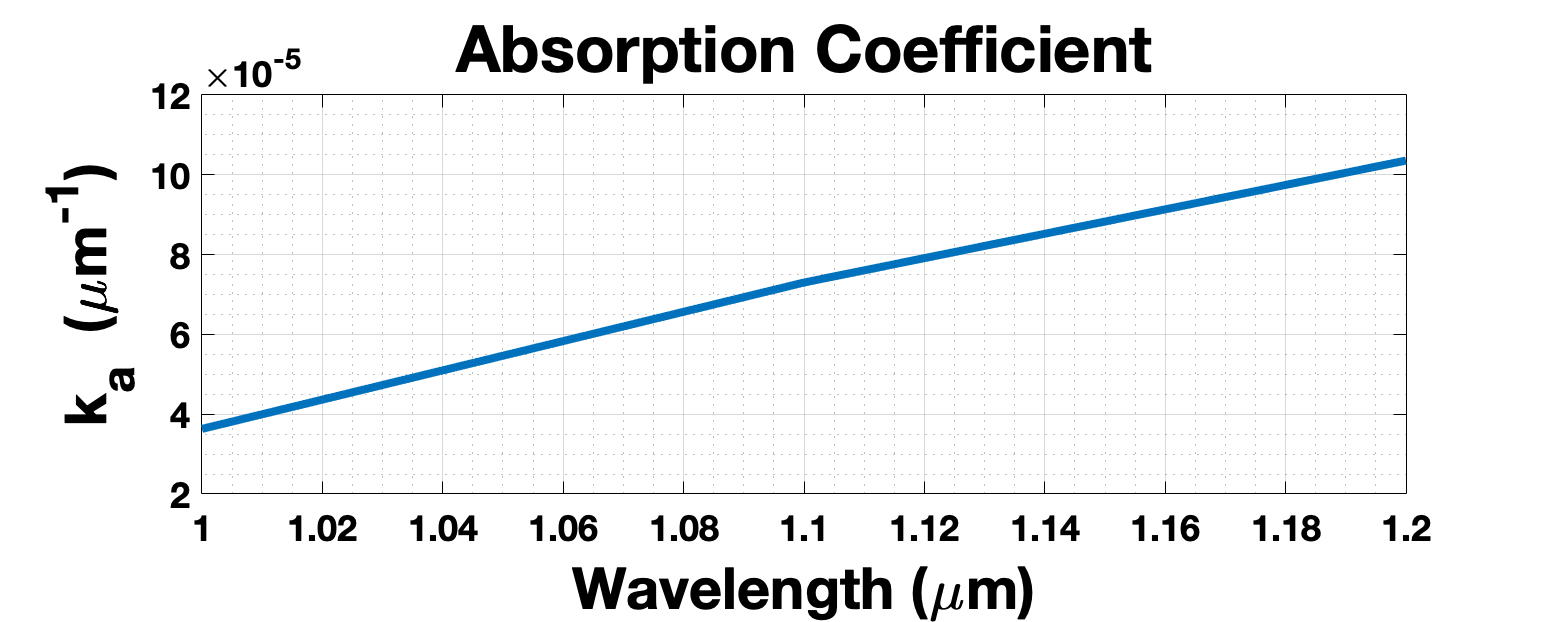


% read in and interpolate values of the complex index of refraction
refrac_ind = interp_refractive_index_H2O(wl_microns);

% Compute the absorption coefficient
k = 4*pi*refrac_ind(:,2)./wl_microns';               % microns^(-1) - absorption coefficient of water

% Lets plot the Results if we have a vector

if length(wl_nm)>1

    f = figure;
    plot(wl_microns, k)
    grid on; grid minor
    xlabel('Wavelength (\mum)')
    ylabel('k_{a}  (\mum^{-1})')
    title('Absorption Coefficient')
    set(f, 'Position', [0 0 1000 400])
end

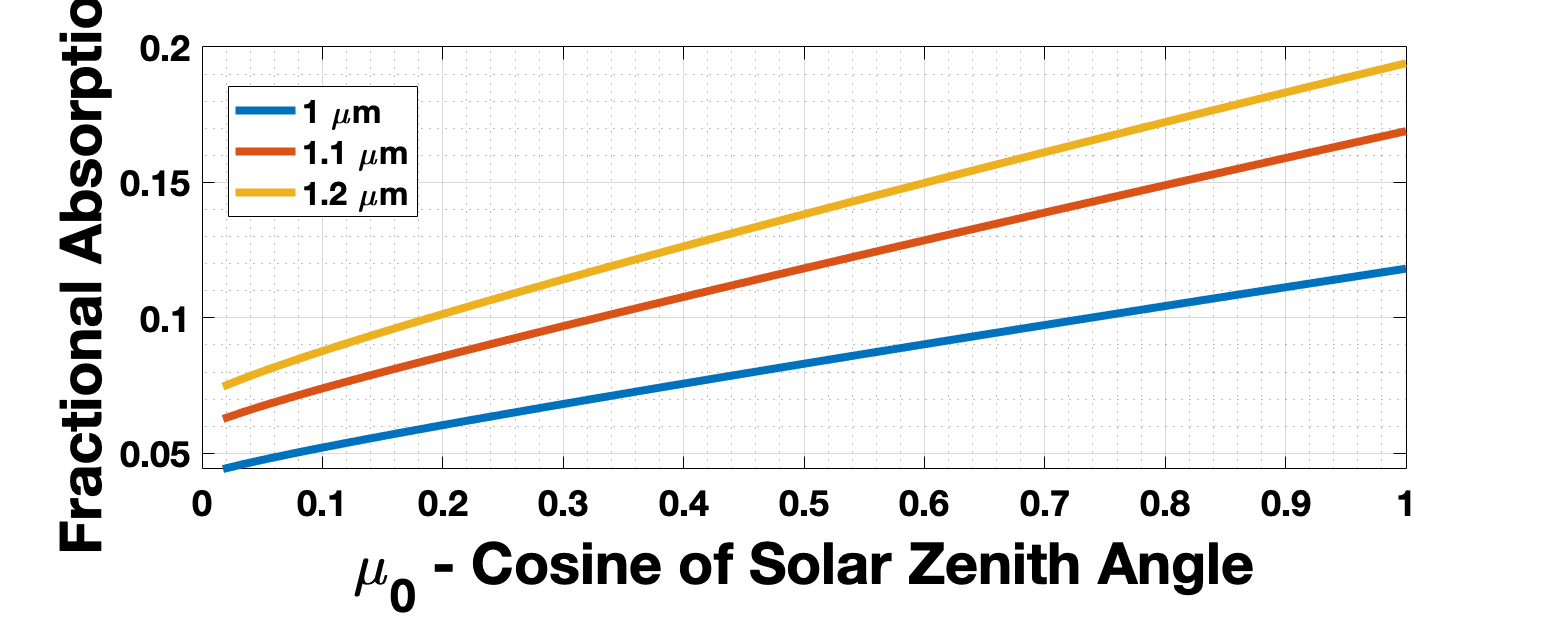



% Compute the fractional absorption. This is equation 8 in Twomey and
% Bohren 1980
A_simp = 2.2 * H_func .* repmat((sqrt(r'.*k))',length(theta0),1);           % unitless - fractional absorption

% Lets plot the Results if we have a vector

f = figure;
plot(mu0, A_simp)
grid on; grid minor
xlabel('\mu_{0} - Cosine of Solar Zenith Angle')
ylabel('Fractional Absorption')
legend(strcat(string(wl_microns),' \mum'), 'Location',"best")
set(f, 'Position', [0 0 1000 400])

## Estimate the Fractional Absoroption for the first 7 MODIS bands

% Lets start by estimating the H function
% define a solar zenith angle
theta0 = 0:89;
mu0 = cosd(theta0);         % cosine of the solar zenith angle

% Pick a wavelength
modis_bands = modisBands(1:7);          % nm
wl_nm = modis_bands(:,1);                    
wl_microns = wl_nm*(1e-3);      % microns
% Pick a droplet radius
r = linspace(10,10,length(wl_nm))';                     % microns

% compute the single scattering albedo

mie_prop = interp_mie_computed_tables([wl_nm,r],'mono',false);
single_scattering_albedo = mie_prop(:,6);
g = mie_prop(:,7);

% Or we can override the singlescattering value to be a specific number of
% interest
%single_scattering_albedo = [0.9996, 0.9998, 0.999]';

% Compute the H function value
H_func = H(mu0, single_scattering_albedo, 0);


% Lets plot the Results!

f = figure;
plot(theta0, H_func)
grid on; grid minor
xlabel('Solar Zenith Angle (deg)')
ylabel('H-Function Value')
legend(strcat(string(wl_microns),' microns'), 'Location',"best")
set(f, 'Position', [0 0 1000 400])

% read in and interpolate values of the complex index of refraction
refrac_ind = interp_refractive_index_H2O(wl_microns);

% Compute the absorption coefficient
k = 4*pi*refrac_ind(:,2)./wl_microns;               % microns^(-1) - absorption coefficient of water

% Lets plot the Results if we have a vector

if length(wl_nm)>1

    f = figure;
    for ii = 1:length(wl_nm)
        semilogy(wl_microns(ii), k(ii), '*')
        hold on;
    end
    
    grid on; grid minor
    xlabel('Wavelength (\mum)')
    ylabel('k_{a}  (\mum^{-1})')
    title('Absorption Coefficient')
    set(f, 'Position', [0 0 1000 400])
end


% Compute the fractional absorption. This is equation 8 in Twomey and
% Bohren 1980
A_simp = 2.2 * H_func .* repmat((sqrt(r.*k))',length(theta0),1);           % unitless - fractional absorption

% Calculate fractional absorption using eq. 3, which doesn't use many
% simplifications
A = H_func.* repmat(sqrt((1 - single_scattering_albedo)./(1 - g.*single_scattering_albedo)), length(theta0),1);

% Lets plot the Results if we have a vector

f = figure;
semilogy(mu0, A_simp)
grid on; grid minor
xlabel('\mu_{0} - Cosine of Solar Zenith Angle')
ylabel('Fractional Absorption')
title('Fractional Absorption of the first 7 MODIS bands')
legend(strcat(string(wl_microns),' \mum'), 'Location',"best")
set(f, 'Position', [0 0 1000 500])


## Compute Fractional Absorption for the first 7 MODIS bands with varrying droplet size

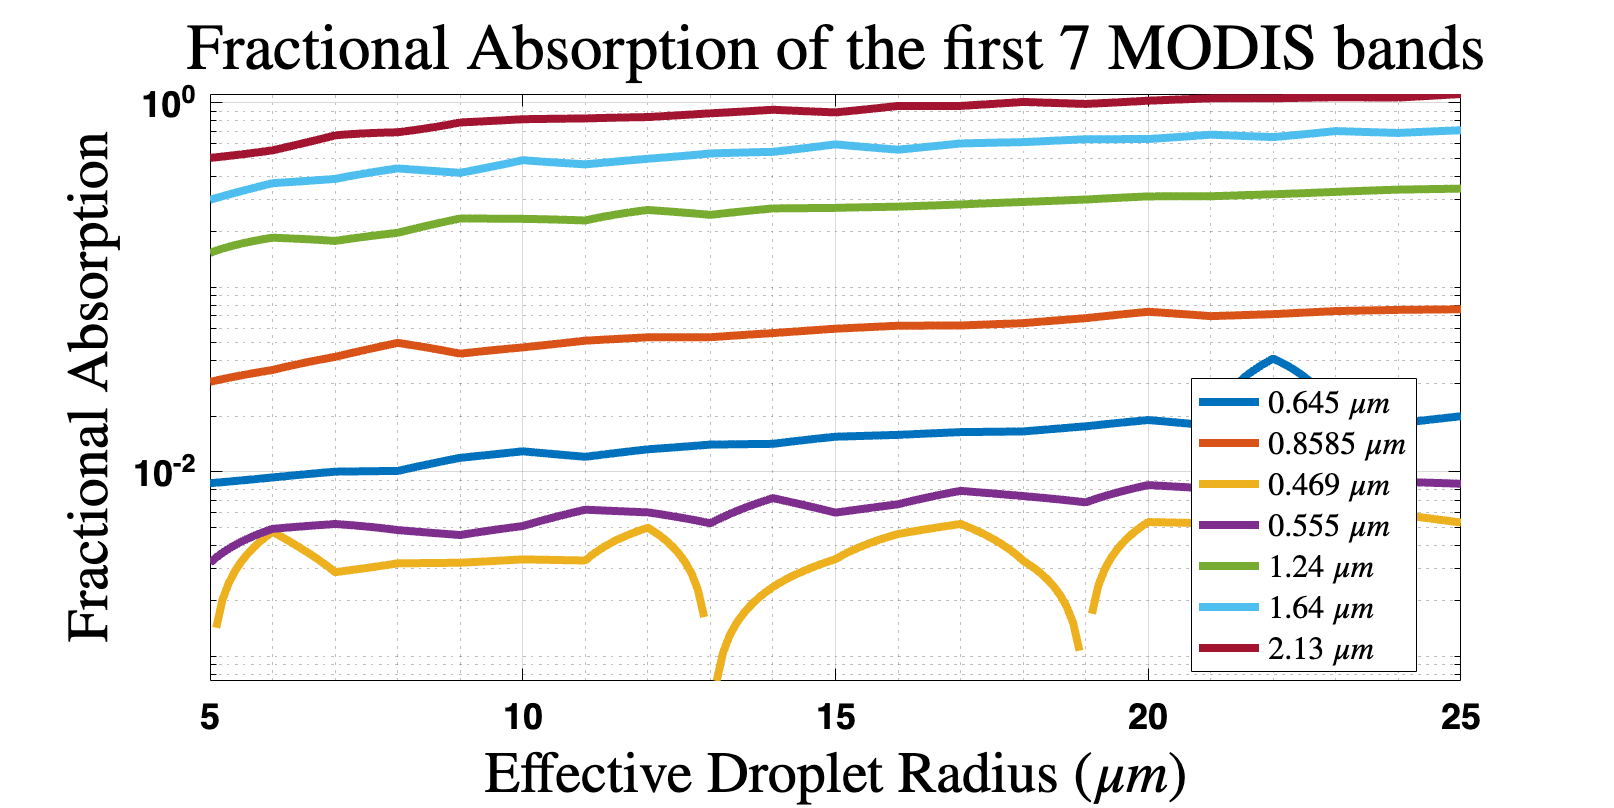

% Lets start by picking a representative solar zenith angle
theta0 = 30;
mu0 = cosd(theta0);         % cosine of the solar zenith angle


% Grab the first 7 MODIS bands
modis_bands = modisBands(1:7);          % nm
wl_nm = modis_bands(:,1);                    
wl_microns = wl_nm*(1e-3);      % microns


% Lets vary the droplet radius across a reasonable range that could be
% measured in a warm liquid cloud
r = 5:0.1:25;                     % microns

% compute the single scattering albedo
mie_prop = zeros(length(wl_nm), 8, length(r));
single_scattering_albedo = zeros(length(wl_nm), length(r));
g = zeros(length(wl_nm), length(r));

% We also need to compute the H function for all single scattering values
H_func = zeros(length(wl_nm), length(r));

for rr = 1:length(r)
    xq = [wl_nm,linspace(r(rr),r(rr),length(wl_nm))'];
    mie_prop(:,:,rr) = interp_mie_computed_tables(xq,'mono',false);
    
    % Grab the single scattering albedo
    single_scattering_albedo(:,rr) = reshape(mie_prop(:,6,rr),length(wl_nm),1);
    g(:,rr) = reshape(mie_prop(:,7,rr),length(wl_nm),1);

    % Compute the H function value
    H_func(:,rr) = H(mu0, single_scattering_albedo(:,rr), 0);
end


% Calculate fractional absorption using eq. 3, which doesn't use many
% simplifications
A = H_func.* sqrt((1 - single_scattering_albedo)./(1 - g.*single_scattering_albedo));


% Lets plot the Results! If A is a matrix, plot() will plot the columns as
% individual vectors

f = figure;
semilogy(r, A')
grid on; grid minor
xlabel('Effective Droplet Radius ($\mu m$)','Interpreter','latex')
ylabel('Fractional Absorption', 'Interpreter','latex')
title('Fractional Absorption of the first 7 MODIS bands', 'Interpreter','latex')
legend(strcat(string(wl_microns),' $\mu m$'), 'Location',"best", 'Interpreter','latex')
set(f, 'Position', [0 0 1000 500])

## Compute Fractional Absorption for all solar wavelengths at a few droplet sizes

% Lets start by picking a representative solar zenith angle
theta0 = 0;
mu0 = cosd(theta0);         % cosine of the solar zenith angle


% Grab the first 7 MODIS bands
wl_nm = 250:2300;                  % nm
wl_microns = wl_nm./1e3;            % microns

% Lets vary the droplet radius across a reasonable range that could be
% measured in a warm liquid cloud
r = 5:5:25;                     % microns

% compute the single scattering albedo
mie_prop = zeros(length(wl_nm), 8, length(r));
single_scattering_albedo = zeros(length(wl_nm), length(r));


g = zeros(length(wl_nm), length(r));

% We also need to compute the H function for all single scattering values
H_func = zeros(length(wl_nm), length(r));

for rr = 1:length(r)
    xq = [wl_nm',linspace(r(rr),r(rr),length(wl_nm))'];
    mie_prop(:,:,rr) = interp_mie_computed_tables(xq,'mono',false);
    
    % Grab the single scattering albedo
    single_scattering_albedo(:,rr) = reshape(mie_prop(:,6,rr),length(wl_nm),1);
    g(:,rr) = reshape(mie_prop(:,7,rr),length(wl_nm),1);

    % Smooth out single scattering albedo. We cannot measure the high frequency
    % content
    single_scattering_albedo(:,rr) = smoothdata(single_scattering_albedo(:,rr), 'gaussian',50);
    g(:,rr) = smoothdata(g(:,rr), 'gaussian', 50);

    % Compute the H function value
    H_func(:,rr) = H(mu0, single_scattering_albedo(:,rr), 0);
end


% Calculate fractional absorption using eq. 3, which doesn't use many
% simplifications
A = H_func.* sqrt((1 - single_scattering_albedo)./(1 - g.*single_scattering_albedo));

% Calculate the simpler absorption
% read in and interpolate values of the complex index of refraction
refrac_ind = interp_refractive_index_H2O(wl_microns);

% Compute the absorption coefficient
k = 4*pi*refrac_ind(:,2)./wl_microns';               % microns^(-1) - absorption coefficient of water

A_simp = H_func.* sqrt((0.85*k*r)./(1 - g.*(1 - 0.85*k*r)));

A_simp2 = 2.2*H_func.*sqrt(k*r);


## Lets plot the Results! 

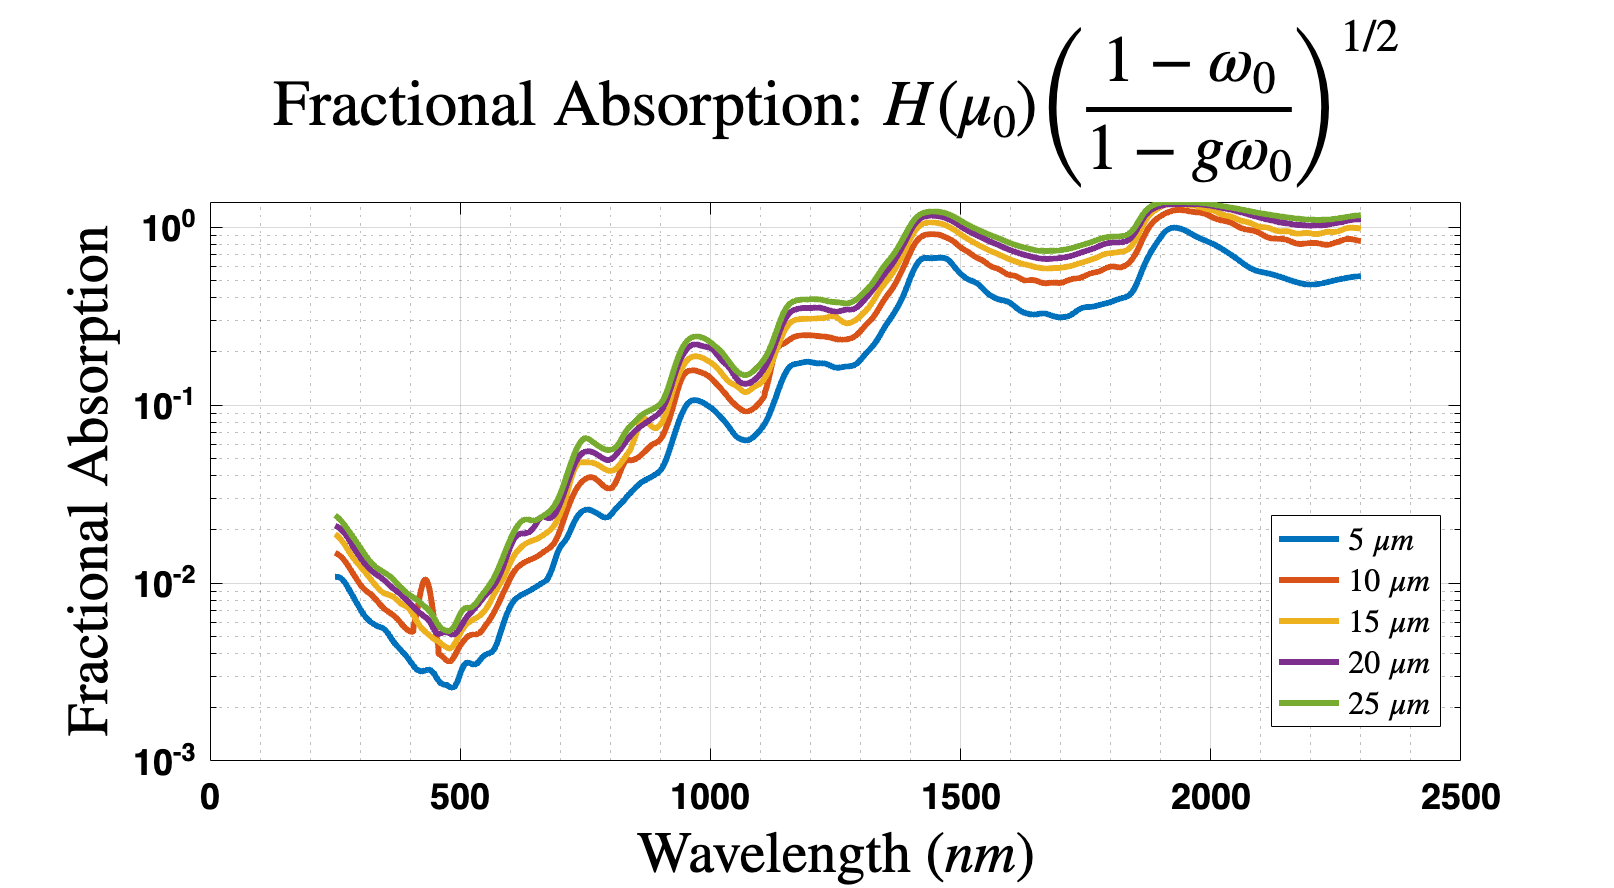

% If A is a matrix, plot() will plot the columns as individual vectors
f = figure;
semilogy(wl_nm, A,'LineWidth',3)
grid on; grid minor
xlabel('Wavelength ($nm$)','Interpreter','latex')
ylabel('Fractional Absorption', 'Interpreter','latex')
title('Fractional Absorption: $H(\mu_0) \left(\frac{1 - \omega_0}{1 - g\omega_0}\right)^{1/2}$', 'Interpreter','latex')
legend(strcat(string(r),' $\mu m$'), 'Location',"best", 'Interpreter','latex')
set(f, 'Position', [0 0 1000 550])

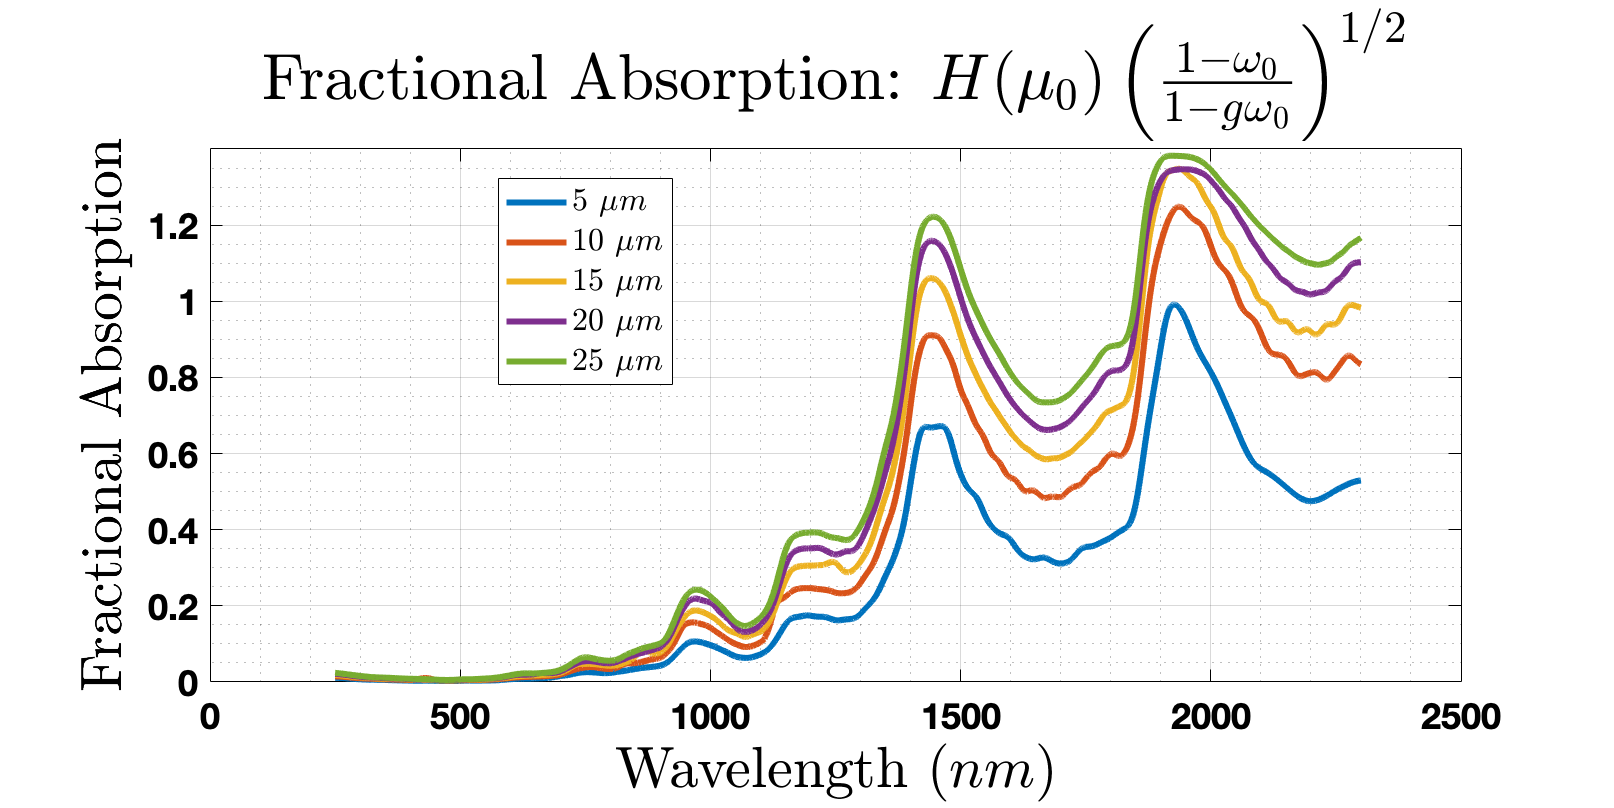


f = figure;
plot(wl_nm, A,'LineWidth',3)
grid on; grid minor
xlabel('Wavelength ($nm$)','Interpreter','latex')
ylabel('Fractional Absorption', 'Interpreter','latex')
title('Fractional Absorption: $H(\mu_0) \left(\frac{1 - \omega_0}{1 - g\omega_0}\right)^{1/2}$', 'Interpreter','latex')
legend(strcat(string(r),' $\mu m$'), 'Location',"best", 'Interpreter','latex')
set(f, 'Position', [0 0 1000 500])

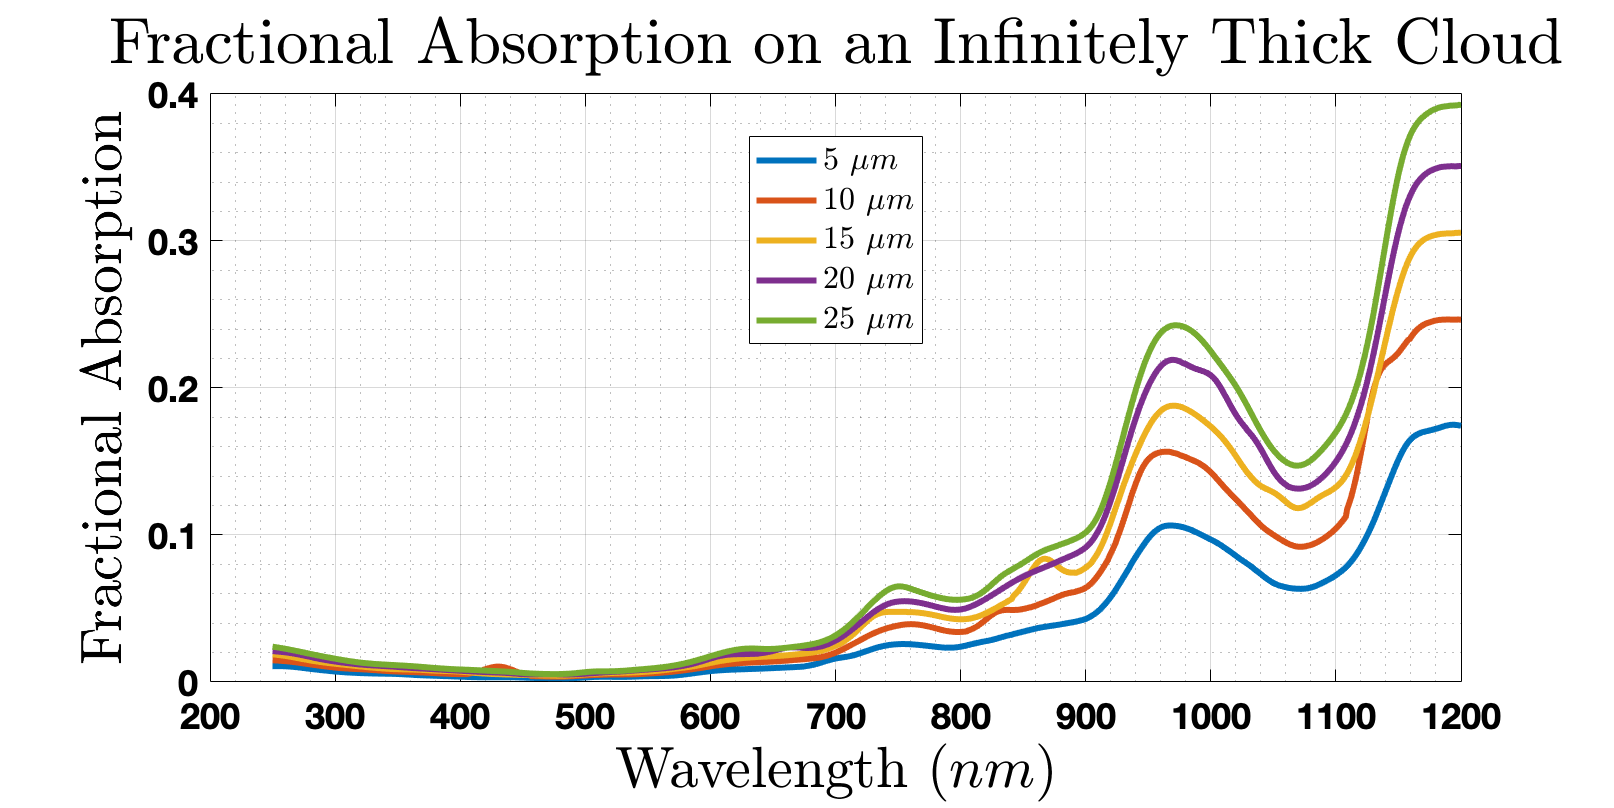

% Plotting the fractional absorptino up to 1.2 microns
f = figure;
plot(wl_nm(wl_nm<=1200), A(wl_nm<=1200,:),'LineWidth',3)
grid on; grid minor
xlabel('Wavelength ($nm$)','Interpreter','latex')
ylabel('Fractional Absorption', 'Interpreter','latex')
title('Fractional Absorption on an Infinitely Thick Cloud', 'Interpreter','latex')
legend(strcat(string(r),' $\mu m$'), 'Location',"best", 'Interpreter','latex')
set(f, 'Position', [0 0 1000 500])

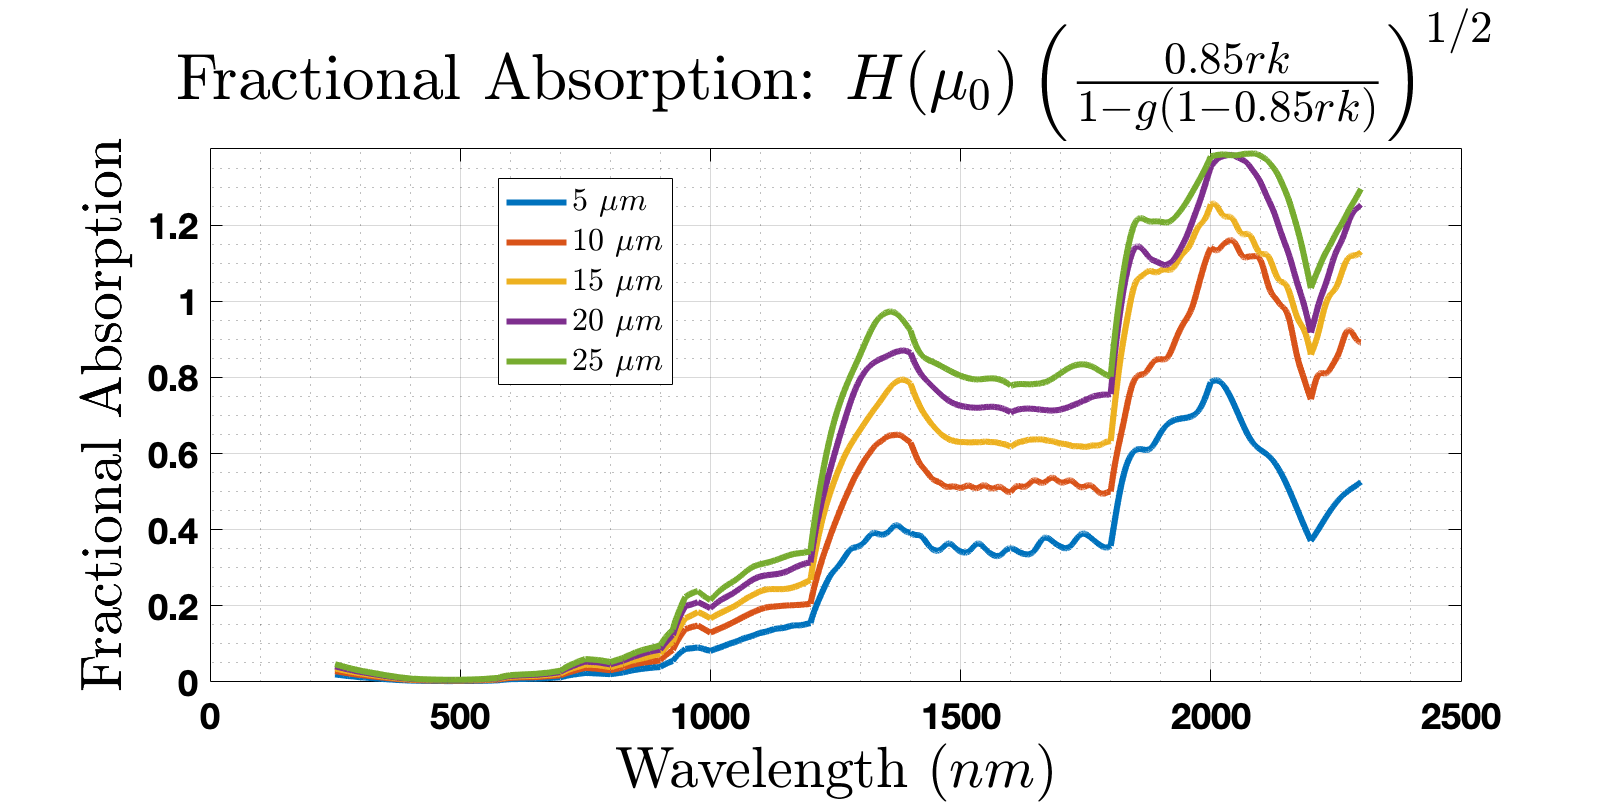



% Plot the simpler calculation
f = figure;
plot(wl_nm, A_simp,'LineWidth',3)
grid on; grid minor
xlabel('Wavelength ($nm$)','Interpreter','latex')
ylabel('Fractional Absorption', 'Interpreter','latex')
title('Fractional Absorption: $H(\mu_0) \left(\frac{0.85 r k}{1 - g(1 - 0.85 r k)}\right)^{1/2}$', 'Interpreter','latex')
legend(strcat(string(r),' $\mu m$'), 'Location',"best", 'Interpreter','latex')
set(f, 'Position', [0 0 1000 500])

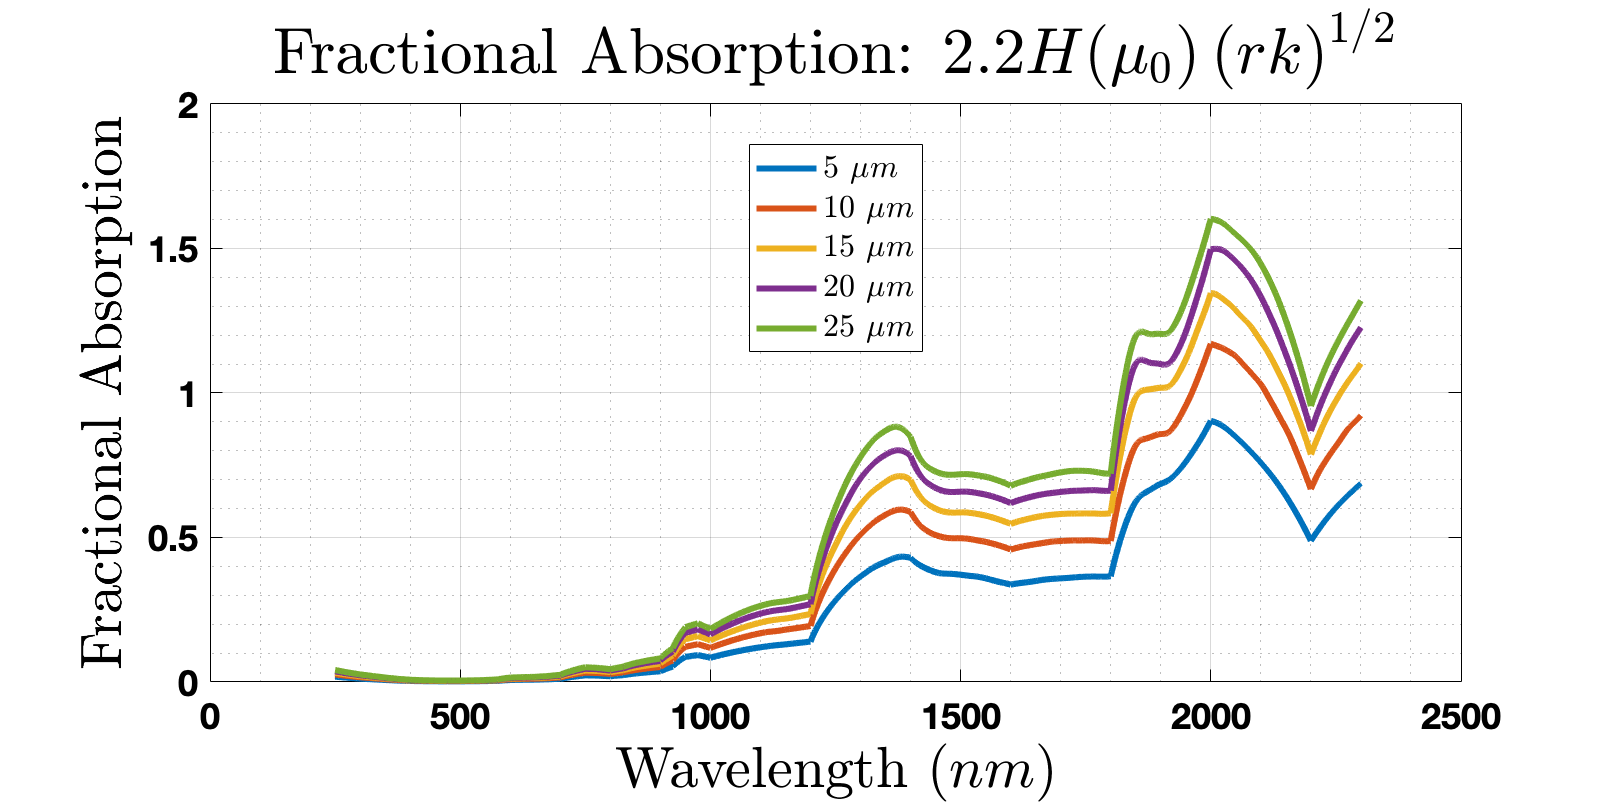


% Plot the simplest form of the calculation
f = figure;
plot(wl_nm, A_simp2,'LineWidth',3)
grid on; grid minor
xlabel('Wavelength ($nm$)','Interpreter','latex')
ylabel('Fractional Absorption', 'Interpreter','latex')
title('Fractional Absorption: $2.2 H(\mu_0) \left(rk\right)^{1/2}$', 'Interpreter','latex')
legend(strcat(string(r),' $\mu m$'), 'Location',"best", 'Interpreter','latex')
set(f, 'Position', [0 0 1000 500])